# Fig 7-A

% data of full model
load('data/res_full');
res = res9;
num_t = length(res.t);
H_ie = reshape(res.H_ie, 25, num_t);
H_ii = reshape(res.H_ii, 25, num_t);
H_ee = reshape(res.H_ee, 75, num_t);
H_ei = reshape(res.H_ei, 75, num_t);
H_ee = sum(H_ee);
H_ie = sum(H_ie);
H_ei = sum(H_ei);
H_ii = sum(H_ii);
H_i = H_ei + H_ii;
H_e = H_ie + H_ee;
N_GE = reshape(res.V_e, 75, num_t);
N_GI = reshape(res.V_i, 25, num_t);
N_GE = sum(N_GE > 45);
N_GI = sum(N_GI > 45);
H_i = H_i(end-1000:end);
H_e = H_e(end-1000:end);
N_GE = N_GE(end-1000:end);
N_GI = N_GI(end-1000: end);

% Coarse grained model
load('data/res_coarse');
res_CG = res6;

N_GE_CG = res_CG.rec(1, :);
N_GI_CG = res_CG.rec(2, :);
H_e_CG = res_CG.rec(3, :);
H_i_CG = res_CG.rec(4, :);
num_t_CG = length(N_GE_CG);
H_i_CG = H_i_CG(end-1000:end);
H_e_CG = H_e_CG(end-1000:end);
N_GE_CG = N_GE_CG(end-1000:end);
N_GI_CG = N_GI_CG(end-1000: end);

Time Curve: Full

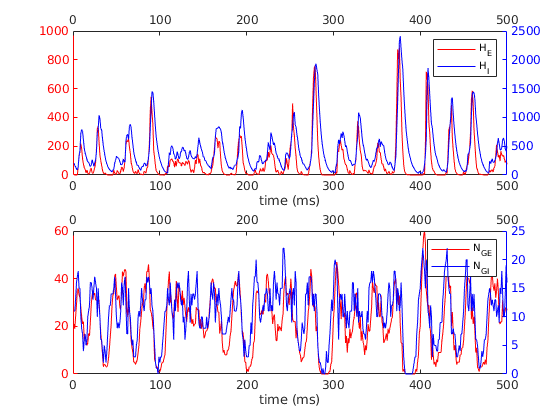

TWin = [0 500];

figure('Name','time lines')
% H
ax1 = subplot(2,1,1);
hold on  
h1 = plot(H_e,'r');

ax1.YColor = [1 0 0];
hold off
ax1_pos = ax1.Position; % position of first axes
xlabel('time (ms)')
xlim(TWin)
ax2 = axes('Position',ax1_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none');
ax2.YColor = [0 0 1];

hold on
h2 = plot(H_i,'b');
xlim(TWin)
legend([h1;h2],{'H_E','H_I'})

% N_G
ax3 = subplot(2,1,2);
hold on  
h1 = plot(N_GE,'r');

ax3.YColor = [1 0 0];
hold off
ax3_pos = ax3.Position; % position of first axes
xlabel('time (ms)')
xlim(TWin)
ax4 = axes('Position',ax3_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none');
ax4.YColor = [0 0 1];

hold on
h2 = plot(N_GI,'b');
xlim(TWin)
legend([h1;h2],{'N_{GE}','N_{GI}'})

Time Curve: CG

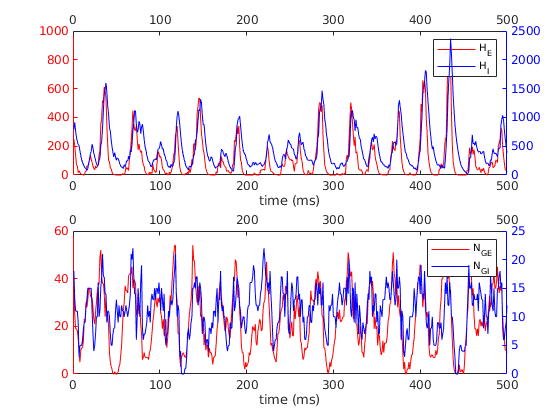

TWin = [0 500];

figure('Name','CG time lines')
% H
ax1 = subplot(2,1,1);
hold on  
h1 = plot(H_e_CG,'r');

ax1.YColor = [1 0 0];
hold off
ax1_pos = ax1.Position; % position of first axes
xlabel('time (ms)')
xlim(TWin)
ax2 = axes('Position',ax1_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none');
ax2.YColor = [0 0 1];

hold on
h2 = plot(H_i_CG,'b');
xlim(TWin)
legend([h1;h2],{'H_E','H_I'})

% N_G
ax3 = subplot(2,1,2);
hold on  
h1 = plot(N_GE_CG,'r');

ax3.YColor = [1 0 0];
hold off
ax3_pos = ax3.Position; % position of first axes
xlabel('time (ms)')
xlim(TWin)
ax4 = axes('Position',ax3_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none');
ax4.YColor = [0 0 1];

hold on
h2 = plot(N_GI_CG,'b');
xlim(TWin)
legend([h1;h2],{'N_{GE}','N_{GI}'})

Full model fig

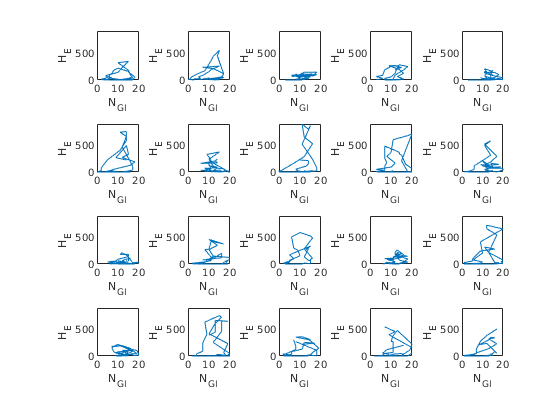

figure('Name','Piecebypiece')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot(N_GI((PlotInd-1)*50+1:PlotInd*50),H_e((PlotInd-1)*50+1:PlotInd*50))
    xlabel('N_{GI}'); ylabel('H_E')
    axis([0 20 0 900])
end

CG fig

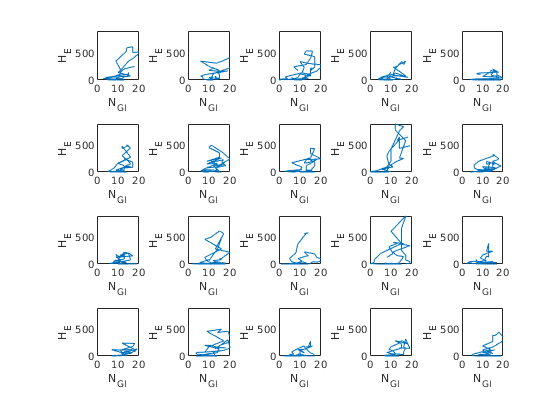

figure('Name','Piecebypiece_CG')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot(N_GI_CG((PlotInd-1)*50+1:PlotInd*50),H_e_CG((PlotInd-1)*50+1:PlotInd*50))
    xlabel('N_{GI}'); ylabel('H_E')
    axis([0 20 0 900])
end

Full model fig

figure('Name','Piecebypiece')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot(H_i((PlotInd-1)*50+1:PlotInd*50),N_GE((PlotInd-1)*50+1:PlotInd*50))
    xlabel('H_I'); ylabel('N_{GE}')
    axis([0 2200 0 70])
end

CG fig

figure('Name','Piecebypiece_CG')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot(H_i_CG((PlotInd-1)*50+1:PlotInd*50),N_GE_CG((PlotInd-1)*50+1:PlotInd*50))
    xlabel('H_I'); ylabel('N_{GE}')
    axis([0 2200 0 70])
end

Full model fig

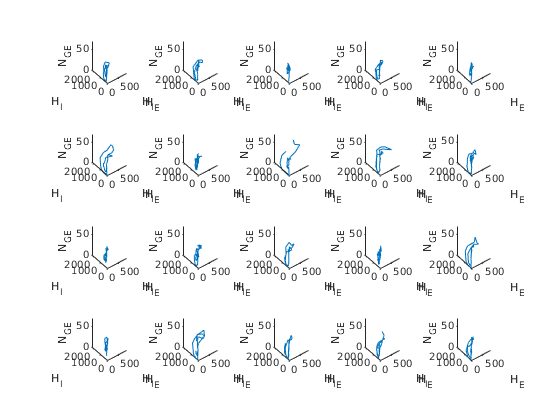

figure('Name','Piecebypiece')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot3(H_e((PlotInd-1)*50+1:PlotInd*50),H_i((PlotInd-1)*50+1:PlotInd*50),N_GE((PlotInd-1)*50+1:PlotInd*50))
    xlabel('H_E');ylabel('H_I'); zlabel('N_{GE}')
    axis([0 900 0 2200  0 70])
end

CG fig

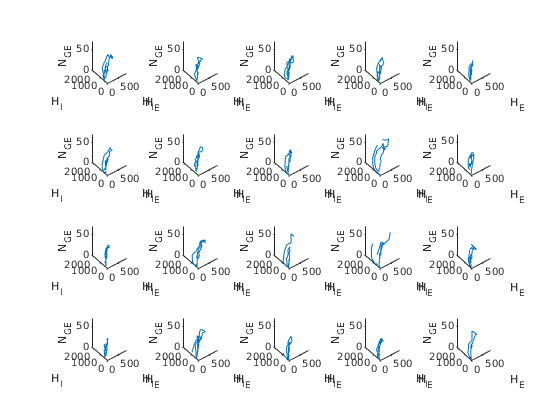

figure('Name','Piecebypiece_CG')
for PlotInd = 1:20
    subplot(4,5,PlotInd)
    plot3(H_e_CG((PlotInd-1)*50+1:PlotInd*50),H_i_CG((PlotInd-1)*50+1:PlotInd*50),N_GE_CG((PlotInd-1)*50+1:PlotInd*50))
    xlabel('H_E');ylabel('H_I'); zlabel('N_{GE}')
    axis([0 900 0 2200 0 70])
end